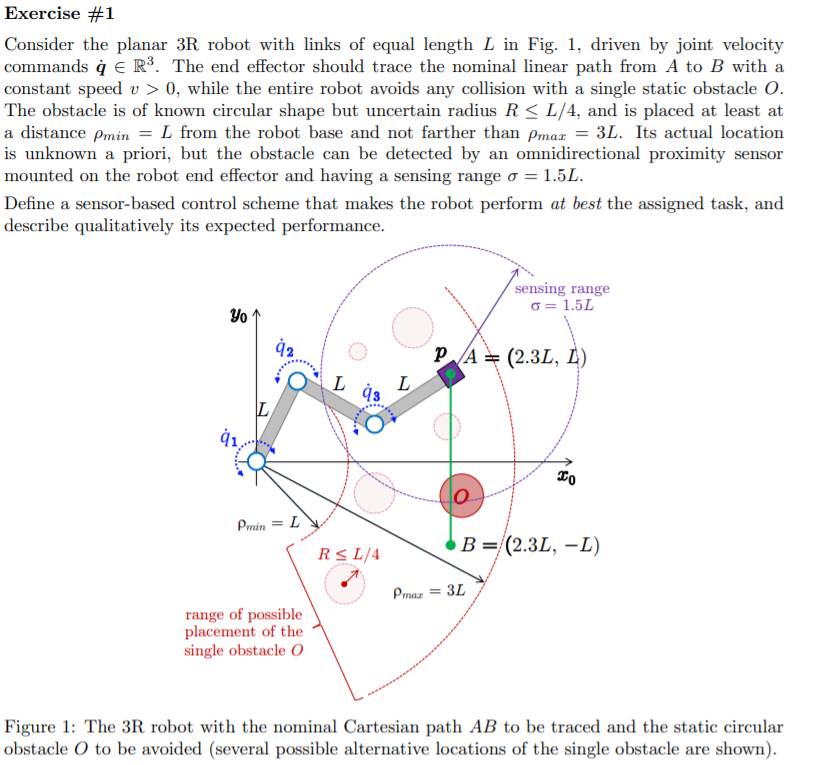

%done by hand


## 2

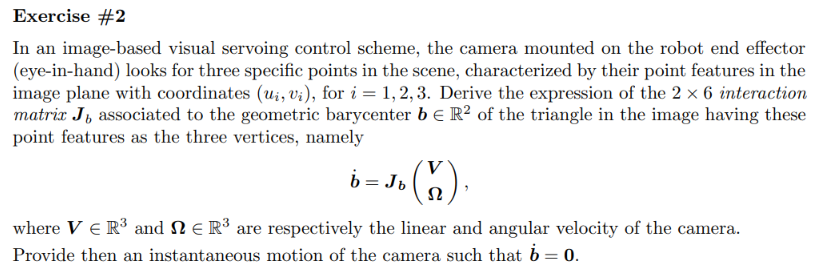

% clc;clear;
% [J_camera,velocities,V,OMEGA]=gen_interaction_matrix(3)

% % J_b=(J_camera{1}+J_camera{2})/2
% J_b=(J_camera{1}+J_camera{2}+J_camera{3})/3
% OMEGA=[0,0,0]' 
% vel_=J_b*[V;OMEGA]

% resn=(simplify(null(J_b),'steps',105)) %one ofthis solutions works well also
% res1=simplify(J_b*resn(:,1),'steps',15)

% % J_b(1,1)
% % J_b(1,3)
% % simplify(J_b(1,3)/J_b(1,1))

% % res=solve([vel_==0;V~=0],[V])

% % % res.Omega_1
% % res.V_1
% % res.V_2
% % res.V_3

## 3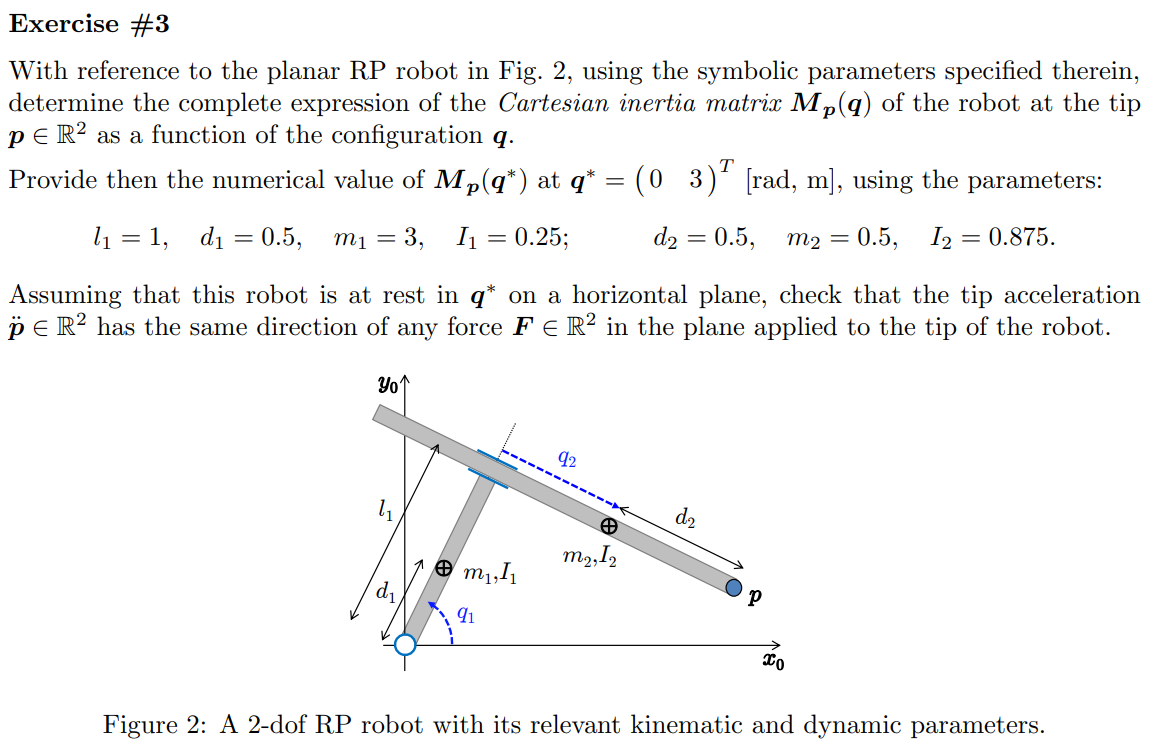

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [1,0];
% R2Robot=['rp';'xy';sigmaD]
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[-q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;
% z.xyonly=true

% 
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)
% 

% Pc
% 
% M
% Trans.PTotal

% J=jacobian(Pc(:,2),z.q)

% J_inv=simplify(pinv(J))
% Mp=(J_inv'*M*J_inv)

% 

% % [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% % cac
% % S

% % [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)

% q_=[0,3]'
% l_=[1,z.l(2)]'
% dc_=[0.5,0.5]'
% m_=[3,0.5]'
% I_=[0.25,0.875]'
% to_replace=[z.q;z.l;z.dc;z.m;z.I]
% to_replace_=[q_;l_;dc_;m_;I_]

% 

% Mp_=vpa(subs(Mp,to_replace,to_replace_))

% J_=subs(J,to_replace,to_replace_)
% M_=subs(M,to_replace,to_replace_)
% J_inv_=pinv(J_)

% Mp_1=(J_inv_'*M_*J_inv_)
% Mp_2=pinv(J_*pinv(M_)*J_') %in this case are exactly the same bu the right way to compute mp is the this method, pay attention!

% F=sym('F_',[3,1],'real')
% p_ddot_=pinv(Mp_)*F

## 4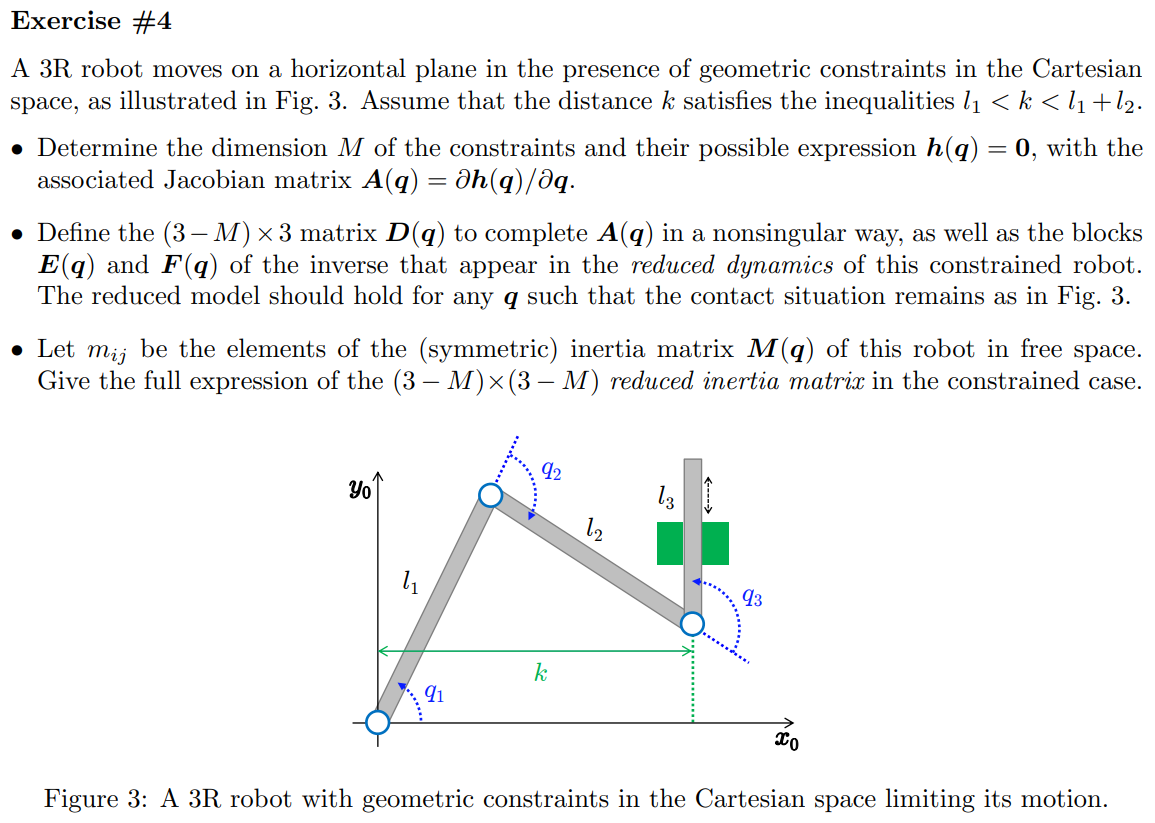

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1,1,1];
R2Robot=['rrr';'xxx';sigmaD]

R2Robot = 3×3 char array
    'rrr'
    'xxx'
    ''


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         


[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×3 char]
                       l: [3×1 sym]
                      l_: []
                       q: [3×1 sym]
                   q_dot: [3×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [3×1 sym]
                       m: [3×1 sym]
                       I: [3×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 3
                  angle_: [0    0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

$$a = l_{3}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$

$$vc = \begin{array}{l} \left(\begin{array}{ccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right) & -{\dot{q}}_{1}\,\left(\sigma_{1}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{3}\right)-{\dot{q}}_{2}\,\left(\sigma_{1}+{\mathrm{dc}}_{3}\,\sigma_{3}\right)-{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sigma_{3}\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right) & {\dot{q}}_{1}\,\left(\sigma_{2}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sigma_{4}\right)+{\dot{q}}_{2}\,\left(\sigma_{2}+{\mathrm{dc}}_{3}\,\sigma_{4}\right)+{\mathrm{dc}}_{3}\,{\dot{q}}_{3}\,\sigma_{4}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=l_{2}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{3}=\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \sigma_{4}=\cos\left(q_{1}+q_{2}+q_{3}\right) \end{array}$$

$$w = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3} \end{array}\right)$$

$$T = \begin{array}{l} \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$Ti = \begin{array}{l} \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} & \frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+\sigma_{1}+{l_{2}}^{2}\right)+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}+2\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{1}+\sigma_{1}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,l_{2}+{l_{2}}^{2}\right)+{{\mathrm{dc}}_{3}}^{2}\,{{\dot{q}}_{3}}^{2}+{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{{\mathrm{dc}}_{3}}^{2}+4\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2}+2\,l_{1}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+2\,{l_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,l_{2}\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{2}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{2}\,\cos\left(q_{3}\right)\right)+2\,{\mathrm{dc}}_{3}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\left({\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{3}\right)\right)\right)}{2}+\frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{3}\right)}^{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

VarShortRobot = struct with fields:
    Pc: [3×3 sym]
    vc: [3×3 sym]
     w: [3×3 sym]
     T: (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2 + (m3*(q_dot_1^2*(dc3^2 + 2*c2_3*dc3*l1 + 2*c3*dc3*l2 + l1^2 + 2*c2*l1*…
    Ti: [1×3 sym]
     M: [3×3 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×3 sym]
               TPartial: {[4×4 sym]  [4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×3 sym]
    Jacobian_dot_PTotal: [3×3 sym]
               PPartial: {[3×1 sym]  [3×1 sym]  [3×1 sym]}
                     Pc: [3×3 sym]
                RTotali: {[3×3 sym]  [3×3 sym]  [3×3 sym]}
           ThetaPartial: [3×1 sym]
             ThetaTotal: q_1 + q_2 + q_3
                     vc: [3×3 sym]
                      w: [3×3 sym]
                      T: (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2 + (m3*(q_dot_2^2*(dc3^2 + 2*cos(q_3)*dc3*l…
                     Ti: [1×3 sym]
                      M: [3×3 sym]


Pc

$$Pc = \left(\begin{array}{ccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\cos\left(q_{1}+q_{2}+q_{3}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right) & l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{3}\,\sin\left(q_{1}+q_{2}+q_{3}\right)\\ 0 & 0 & 0 \end{array}\right)$$


M

$$M = \begin{array}{l} \left(\begin{array}{ccc} I_{1}+I_{2}+I_{3}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{2}}^{2}\,m_{2}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{2}}^{2}\,m_{3}+2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+2\,{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\cos\left(q_{2}\right)+2\,{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)+2\,l_{1}\,l_{2}\,m_{3}\,\cos\left(q_{2}\right) & \sigma_{3} & \sigma_{1}\\ \sigma_{3} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+m_{3}\,{l_{2}}^{2}+I_{2}+I_{3} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & m_{3}\,{{\mathrm{dc}}_{3}}^{2}+I_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=I_{3}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)+{\mathrm{dc}}_{3}\,l_{2}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{2}=m_{3}\,{{\mathrm{dc}}_{3}}^{2}+l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}+I_{3}\\ \sigma_{3}=m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+m_{3}\,{{\mathrm{dc}}_{3}}^{2}+\sigma_{4}+l_{1}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)\,{\mathrm{dc}}_{3}+m_{3}\,{l_{2}}^{2}+l_{1}\,m_{3}\,\cos\left(q_{2}\right)\,l_{2}+I_{2}+I_{3}\\ \sigma_{4}=2\,m_{3}\,\cos\left(q_{3}\right)\,{\mathrm{dc}}_{3}\,l_{2} \end{array}$$

Trans.PTotali(:,2)

$$ans = \left(\begin{array}{c} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

k=sym('k','real')

$$k = k$$

A_sym=sym('A',[n,n],'real')

$$A\_sym = \left(\begin{array}{ccc} A_{1,1} & A_{1,2} & A_{1,3}\\ A_{2,1} & A_{2,2} & A_{2,3}\\ A_{3,1} & A_{3,2} & A_{3,3} \end{array}\right)$$

h=[sum(z.q)-pi-2;Trans.PTotali(1,2)-k]

$$h = \left(\begin{array}{c} q_{1}+q_{2}+q_{3}-\pi -2\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)-k+l_{1}\,\cos\left(q_{1}\right) \end{array}\right)$$

D_int=Trans.PTotali(2,2)

$$D\_int = l_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)$$

A=jacobian(h,z.q)

$$A = \left(\begin{array}{ccc} 1 & 1 & 1\\ -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0 \end{array}\right)$$

D=jacobian(D_int,z.q)

$$D = \left(\begin{array}{ccc} l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) & 0 \end{array}\right)$$

## Finding D

A_sym2=A_sym;
A_sym2(1:2,:)=A

$$A\_sym2 = \left(\begin{array}{ccc} 1 & 1 & 1\\ -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0\\ A_{3,1} & A_{3,2} & A_{3,3} \end{array}\right)$$

A_sym2(3,:)=D

$$A\_sym2 = \left(\begin{array}{ccc} 1 & 1 & 1\\ -l_{2}\,\sin\left(q_{1}+q_{2}\right)-l_{1}\,\sin\left(q_{1}\right) & -l_{2}\,\sin\left(q_{1}+q_{2}\right) & 0\\ l_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{1}+q_{2}\right) & 0 \end{array}\right)$$

det(A_sym2)

$$ans = l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\cos\left(q_{1}\right)-l_{1}\,l_{2}\,\cos\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)$$

simplify(det(A_sym2),'steps',15)

$$ans = l_{1}\,l_{2}\,\sin\left(q_{2}\right)$$

[dyn_red]=dynamics_reduction(h,D,z)

dyn_red = struct with fields:
    M_red: -(M_1_2*l2^2*sin(q_1 + q_2)^2 - M_1_1*l2^2*sin(q_1 + q_2)^2 + M_2_1*l2^2*sin(q_1 + q_2)^2 - M_2_2*l2^2*sin(q_1 + q_2)^2 - M_2_2*l1^2*sin(q_1)^2 + M_2_3*l1^2*sin(q_1)^2 + M_3_2*l1^2*sin(q_1)^2 - M_3_3*l1^2*sin(q_1)^2 + M_1_2*l1*l2*sin(q_1 +…
        A: [2×3 sym]
        D: [l2*cos(q_1 + q_2) + l1*cos(q_1)    l2*cos(q_1 + q_2)    0]
        E: [3×2 sym]
        F: [3×1 sym]
        v: q_dot_1*(l2*cos(q_1 + q_2) + l1*cos(q_1)) + l2*q_dot_2*cos(q_1 + q_2)


dyn_red.M_red

$$ans = \begin{array}{l} -\frac{M_{1,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{1,1}\,{l_{2}}^{2}\,\sigma_{1}+M_{2,1}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{2,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{3,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}-M_{3,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{1,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{1,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-2\,M_{2,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{3,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{3,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)}{{l_{1}}^{2}\,{l_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(q_{1}+q_{2}\right)}^{2} \end{array}$$

## reduced M

M_sym=sym('M_',[n,n],'real')

$$M\_sym = \left(\begin{array}{ccc} M_{1,1} & M_{1,2} & M_{1,3}\\ M_{2,1} & M_{2,2} & M_{2,3}\\ M_{3,1} & M_{3,2} & M_{3,3} \end{array}\right)$$

to_collect=[sin(z.q(1)+z.q(2)),sin(z.q(1))]

$$to\_collect = \left(\begin{array}{cc} \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}\right) \end{array}\right)$$


r_side_M=(collect(simplify(M_sym*dyn_red.F),to_collect))%,to_collect2)

$$r\_side\_M = \begin{array}{l} \left(\begin{array}{c} \frac{M_{1,1}\,l_{2}-M_{1,2}\,l_{2}}{\sigma_{1}}\,\sin\left(q_{1}+q_{2}\right)+\left(-\frac{M_{1,2}\,l_{1}-M_{1,3}\,l_{1}}{\sigma_{1}}\right)\,\sin\left(q_{1}\right)\\ \frac{M_{2,1}\,l_{2}-M_{2,2}\,l_{2}}{\sigma_{1}}\,\sin\left(q_{1}+q_{2}\right)+\left(-\frac{M_{2,2}\,l_{1}-M_{2,3}\,l_{1}}{\sigma_{1}}\right)\,\sin\left(q_{1}\right)\\ \frac{M_{3,1}\,l_{2}-M_{3,2}\,l_{2}}{\sigma_{1}}\,\sin\left(q_{1}+q_{2}\right)+\left(-\frac{M_{3,2}\,l_{1}-M_{3,3}\,l_{1}}{\sigma_{1}}\right)\,\sin\left(q_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{1}\,l_{2}\,\sin\left(q_{2}\right) \end{array}$$

M_red=simplify(dyn_red.F'*M_sym*dyn_red.F)

$$M\_red = \begin{array}{l} -\frac{M_{1,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{1,1}\,{l_{2}}^{2}\,\sigma_{1}+M_{2,1}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{2,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{3,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}-M_{3,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{1,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{1,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-2\,M_{2,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{3,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{3,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)}{{l_{1}}^{2}\,{l_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(q_{1}+q_{2}\right)}^{2} \end{array}$$

simplify(M_red,'steps',150)

$$ans = \begin{array}{l} -\frac{M_{1,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{1,1}\,{l_{2}}^{2}\,\sigma_{1}+M_{2,1}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{2,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{3,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}-M_{3,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{1,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{1,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-2\,M_{2,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{3,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{3,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)}{{l_{1}}^{2}\,{l_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(q_{1}+q_{2}\right)}^{2} \end{array}$$


% to_collect2=[1/sin(z.q(2)),sin(z.q(1)+z.q(2))^2,sin(z.q(1))^2]
% to_collect2=[sin(z.q(1))^2,sin(z.q(1)+z.q(2))^2,(l(1)*l(2)/sin(z.q(2)))^2]
temp_factor=(l(1)^2)*(l(2)^2)*sin(q(2))^2

$$temp\_factor = {l_{1}}^{2}\,{l_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}$$

M_red2=simplify(simplify(dyn_red.M_red))

$$M\_red2 = \begin{array}{l} -\frac{M_{1,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{1,1}\,{l_{2}}^{2}\,\sigma_{1}+M_{2,1}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{2}}^{2}\,\sigma_{1}-M_{2,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{2,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{3,2}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}-M_{3,3}\,{l_{1}}^{2}\,{\sin\left(q_{1}\right)}^{2}+M_{1,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{1,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-2\,M_{2,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{2,3}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)-M_{3,1}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)+M_{3,2}\,l_{1}\,l_{2}\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)}{{l_{1}}^{2}\,{l_{2}}^{2}\,{\sin\left(q_{2}\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}={\sin\left(q_{1}+q_{2}\right)}^{2} \end{array}$$

% 
% to_collect2=[sin(z.q(1))^2,sin(z.q(1)+z.q(2))^2,sin(z.q(1)+z.q(2)),sin(z.q(1))]%,sin(z.q(1)+z.q(2))^2,(l(1)*l(2)/sin(z.q(2)))^2]
to_collect2=[sin(z.q(1)+z.q(2)),sin(z.q(1)),l']

$$to\_collect2 = \left(\begin{array}{ccccc} \sin\left(q_{1}+q_{2}\right) & \sin\left(q_{1}\right) & l_{1} & l_{2} & l_{3} \end{array}\right)$$

(collect(simplify(M_red2),to_collect2))

$$ans = \frac{\left(M_{1,1}-M_{1,2}-M_{2,1}+M_{2,2}\right)\,{\sin\left(q_{1}+q_{2}\right)}^{2}\,{l_{2}}^{2}+\left(M_{1,3}-M_{1,2}-M_{2,1}+2\,M_{2,2}-M_{2,3}+M_{3,1}-M_{3,2}\right)\,\sin\left(q_{1}+q_{2}\right)\,\sin\left(q_{1}\right)\,l_{1}\,l_{2}+\left(M_{2,2}-M_{2,3}-M_{3,2}+M_{3,3}\right)\,{\sin\left(q_{1}\right)}^{2}\,{l_{1}}^{2}}{{\sin\left(q_{2}\right)}^{2}\,{l_{1}}^{2}\,{l_{2}}^{2}}$$

## 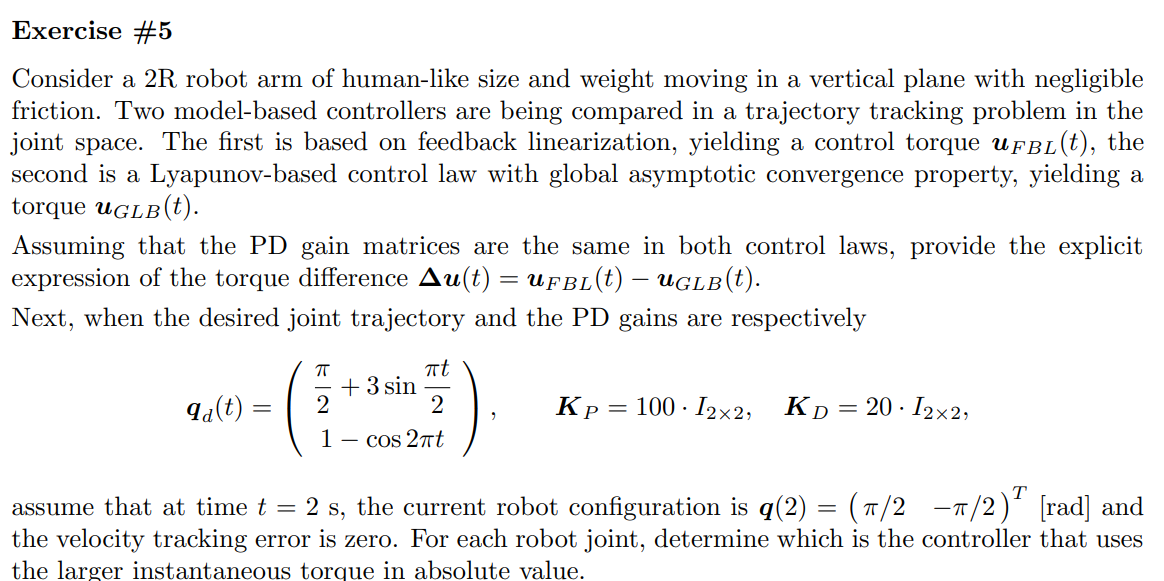

% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [1,1];
R2Robot=['rr';'xx';sigmaD]

R2Robot = 3×2 char array
    'rr'
    'xx'
    ''


n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';

z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
% z.angle_(2)=sym(pi);
% z.opt_expr={[q(2)],[-q(2)]};
% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

% 
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$vc = \left(\begin{array}{cc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -{\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\right)-{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & {\dot{q}}_{1}\,\left({\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\right)+{\mathrm{dc}}_{2}\,{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0 \end{array}\right)$$

$$w = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} \end{array}\right)$$

$$T = \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{m_{2}\,\left(\left({{\mathrm{dc}}_{2}}^{2}+2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+{l_{1}}^{2}\right)\,{{\dot{q}}_{1}}^{2}+\left(2\,{{\mathrm{dc}}_{2}}^{2}+2\,l_{1}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\right)\,{\dot{q}}_{1}\,{\dot{q}}_{2}+{{\mathrm{dc}}_{2}}^{2}\,{{\dot{q}}_{2}}^{2}\right)}{2}+\frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2} \end{array}\right)$$

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

VarShortRobot = struct with fields:
    Pc: [3×2 sym]
    vc: [3×2 sym]
     w: [3×2 sym]
     T: (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2
    Ti: [(q_dot_1^2*(m1*dc1^2 + I1))/2    (m2*(q_dot_1^2*(dc2^2 + 2*c2*dc2*l1 + l1^2) + dc2^2*q_dot_2^2 + q_dot_1*q_dot_2*(2*dc2^2 + 2*c2*l1*dc2)))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2]
     M: [2×2 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×2 sym]
               TPartial: {[4×4 sym]  [4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]  [3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×2 sym]
    Jacobian_dot_PTotal: [3×2 sym]
               PPartial: {[3×1 sym]  [3×1 sym]}
                     Pc: [3×2 sym]
                RTotali: {[3×3 sym]  [3×3 sym]}
           ThetaPartial: [2×1 sym]
             ThetaTotal: q_1 + q_2
                     vc: [3×2 sym]
                      w: [3×2 sym]
                      T: (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q_dot_1 + q_dot_2)^2)/2 + (q_dot_1^2*(m1*dc1^2 + I1))/2
                     Ti: [(q_dot_1^2*(m1*dc1^2 + I1))/2    (m2*((dc2^2 + 2*cos(q_2)*dc2*l1 + l1^2)*q_dot_1^2 + (2*dc2^2 + 2*l1*cos(q_2)*dc2)*q_dot_1*q_dot_2 + dc2^2*q_dot_2^2))/2 + (I2*(q

% 

Pc

$$Pc = \left(\begin{array}{cc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & {\mathrm{dc}}_{2}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

% 
M

$$M = \left(\begin{array}{cc} m_{1}\,{{\mathrm{dc}}_{1}}^{2}+m_{2}\,{{\mathrm{dc}}_{2}}^{2}+2\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}\,l_{1}+m_{2}\,{l_{1}}^{2}+I_{1}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2}\\ m_{2}\,{{\mathrm{dc}}_{2}}^{2}+l_{1}\,m_{2}\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{2}+I_{2} & m_{2}\,{{\mathrm{dc}}_{2}}^{2}+I_{2} \end{array}\right)$$

% Trans.PTotal

% J=jacobian(Pc(:,2),z.q)

% J_inv=simplify(pinv(J))
% Mp=(J_inv'*M*J_inv)

% 

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$cac = \left(\begin{array}{c} -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right) \end{array}\right)$$

Csubs = 1×2 cell array
    {2×2 sym}    {2×2 sym}


$$S = \left(\begin{array}{cc} -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -{\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,\sin\left(q_{2}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ {\mathrm{dc}}_{2}\,l_{1}\,m_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

cac
S

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor);

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cccccc} \sin\left(q_{1}\right) & \sin\left(q_{2}\right) & \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

$$PE = g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)$$

$$PE\_short = g_{0}\,\sin\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\sin\left(q_{1}+q_{2}\right)$$

$$g\_q\_short = \left(\begin{array}{c} g_{0}\,\cos\left(q_{1}\right)\,\left({\mathrm{dc}}_{1}\,m_{1}+l_{1}\,m_{2}\right)+{\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right)\\ {\mathrm{dc}}_{2}\,g_{0}\,m_{2}\,\cos\left(q_{1}+q_{2}\right) \end{array}\right)$$

% [Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[],2)
[All, dynamicParameters, aM] = getDynamicParameters3([M,S,g_q],z.q,[z.q_dot],2);

>> Getting dynamic coefficients. Might take a while...


Msubs=All(:,1:n)

$$Msubs = \left(\begin{array}{cc} a_{5}+2\,a_{2}\,\cos\left(q_{2}\right) & a_{3}+a_{2}\,\cos\left(q_{2}\right)\\ a_{3}+a_{2}\,\cos\left(q_{2}\right) & a_{3} \end{array}\right)$$

Ssubs=All(:,n+1:2*n)

$$Ssubs = \left(\begin{array}{cc} -a_{2}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right) & -\sin\left(q_{2}\right)\,\left(a_{2}\,{\dot{q}}_{1}+a_{2}\,{\dot{q}}_{2}\right)\\ a_{2}\,{\dot{q}}_{1}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

Gsubs=All(:,2*n+1)

$$Gsubs = \left(\begin{array}{c} a_{4}\,\cos\left(q_{1}\right)+a_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-a_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ a_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-a_{1}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) \end{array}\right)$$

aM

$$aM = \left(\begin{array}{c} a_{1}\\ a_{2}\\ a_{3}\\ a_{4}\\ a_{5} \end{array}\right)$$

t=sym('t','real')

$$t = t$$

q_d         =[pi/2+3*sin(pi*t/2),1-cos(2*pi*t)]'

$$q\_d = \left(\begin{array}{c} \frac{\pi }{2}+3\,\sin\left(\frac{\pi \,t}{2}\right)\\ 1-\cos\left(2\,\pi \,t\right) \end{array}\right)$$

q_d_dot     =simplify(diff(q_d))

$$q\_d\_dot = \left(\begin{array}{c} \frac{3\,\pi \,\cos\left(\frac{\pi \,t}{2}\right)}{2}\\ 2\,\pi \,\sin\left(2\,\pi \,t\right) \end{array}\right)$$

t_=2

t_ = 2

q_      =[pi/2,-pi/2]'

q_ =     1.5708
   -1.5708



% q_d_    =[pi/2+3*sin(pi*t_/2),1-cos(2*pi*t_)]'

% l_=[1,z.l(2)]'
% dc_=[0.5,0.5]'
% m_=[3,0.5]'
% I_=[0.25,0.875]'
to_replace=[z.q;t]

$$to\_replace = \left(\begin{array}{c} q_{1}\\ q_{2}\\ t \end{array}\right)$$

to_replace_=[q_;t_]

to_replace_ =     1.5708
   -1.5708
    2.0000


q_d_=(subs(q_d,to_replace,to_replace_))

$$q\_d\_ = \left(\begin{array}{c} \frac{\pi }{2}\\ 0 \end{array}\right)$$

q_d_dot_=(subs(q_d_dot,to_replace,to_replace_))

$$q\_d\_dot\_ = \left(\begin{array}{c} -\frac{3\,\pi }{2}\\ 0 \end{array}\right)$$

q_dot_ =q_d_dot_

$$q\_dot\_ = \left(\begin{array}{c} -\frac{3\,\pi }{2}\\ 0 \end{array}\right)$$

% q_d_dot_  =[0,0]'
e_=q_d_-q_

$$e\_ = \left(\begin{array}{c} 0\\ \frac{\pi }{2} \end{array}\right)$$


e_dot_=q_d_dot_-q_dot_

$$e\_dot\_ = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$


to_replace=[z.q;z.q_dot;t]

$$to\_replace = \left(\begin{array}{c} q_{1}\\ q_{2}\\ {\dot{q}}_{1}\\ {\dot{q}}_{2}\\ t \end{array}\right)$$

to_replace_=[q_;q_dot_;t_]

$$to\_replace\_ = \left(\begin{array}{c} \frac{\pi }{2}\\ -\frac{\pi }{2}\\ -\frac{3\,\pi }{2}\\ 0\\ 2 \end{array}\right)$$

M_=vpa(subs(Msubs,to_replace,to_replace_))

$$M\_ = \left(\begin{array}{cc} a_{5} & a_{3}\\ a_{3} & a_{3} \end{array}\right)$$

S_=vpa(subs(Ssubs,to_replace,to_replace_))

$$S\_ = \left(\begin{array}{cc} 0 & -4.7123889803846898576939650749193\,a_{2}\\ 4.7123889803846898576939650749193\,a_{2} & 0 \end{array}\right)$$

K_D=diag([20,20])

K_D =     20     0
     0    20


K_P=diag([100,100])

K_P =    100     0
     0   100


K_res_=((K_D*e_dot_+K_P*e_))

$$K\_res\_ = \left(\begin{array}{c} 0\\ 50\,\pi \end{array}\right)$$

% 50*pi
delta_u_=((M_-eye(size(M)))*K_res_)

$$delta\_u\_ = \left(\begin{array}{c} 50\,\pi \,a_{3}\\ 50\,\pi \,\left(a_{3}-1\right) \end{array}\right)$$